## Lesli model

sys_no_interspec = function_handle with value:
    @(t,x)[eps1*x(1)-gam1*x(1)*x(2);gam2*x(1)*x(2)-eps2*x(2)]


init1 =      0
     0


init2 =     0.6667
    0.7500


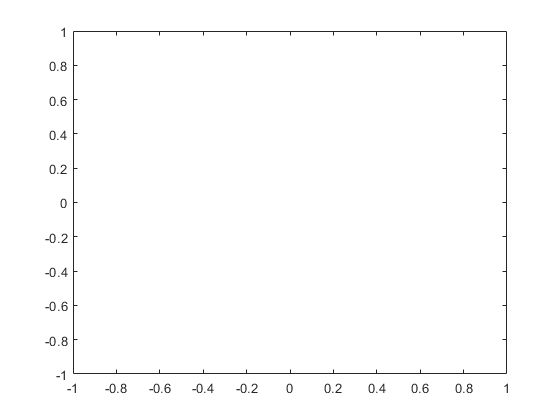

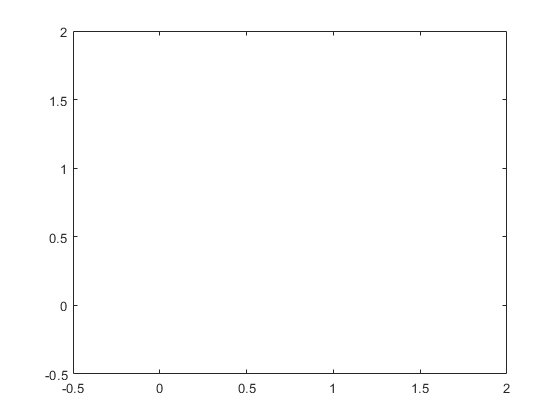

init1 =      0
     0


init2 =     0.6667
    0.7500


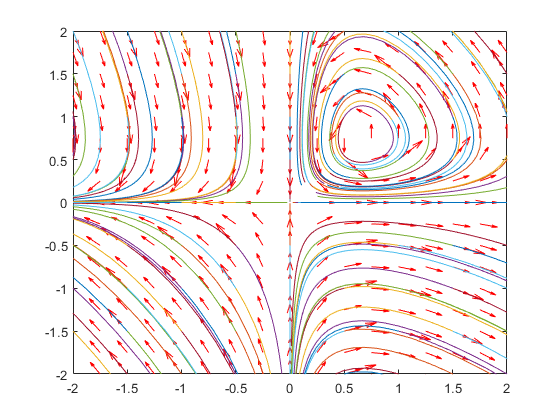


%{
L = [0, 8, 15; 1/3, 0, 0; 0, 1/2, 0];

x0 = [0, 1, 1];
[vals, vecs] = eig(L);
eig_vals = diag(vals)
lamb = max(eig_vals)

ind = vals == lamb;
vals(ind);

n = size(L);
n = n(1);
n = 1:n;

indxs = n(ind);
x_L = vecs(indxs,:)

t = 8;
x_t = (L^t) * x0'
x_t(1)
x_t(2)
x_t(3)

x = x0'
while (sum(x) <= 110)
    x1 = x;
    x = L * x;
end
x
x1

%}

## simple ode

%{

left = 0;
right = 45;
t1 = 40;

syms p(t);
ode1 = diff(p,t) == 0.0004 * p * (150 - p)
cond1 = p(0) == 20

P1 = dsolve(ode1,cond1)

figure;
hold on;
fplot(P1,[left, right]);

cond2 = p(0) == 300

P2 = dsolve(ode1,cond2)
fplot(P2,[left, right]);

y1 = double(subs(P1, 40))
y2 = double(subs(P2, 40))

%}